## **基于ADS Interface的ADS-Matlab联合仿真优化参数速度匹配**

作者：FTT

clc
clear
close all

### **初始化ADS接口**

% 重要！！！必须把包含接口类的文件夹添加到路径！！！
addpath D:\Documents\GitHub\MyMatlabCode\基于广义传输矩阵的速度匹配优化方法\Source\TADSInterface
% 定义ADS接口对象
ADS = TADSInterface();
% 设置ADS安装目录
ADSInstallationDir = 'D:\Program Files\Keysight\ADS2022';
ADS.SetADSPaths(ADSInstallationDir);

[ADS][14:55:01] All required environmental variables and paths are set and checked.


% 设置参数文件的路径（以netlist.log命名）
ADS.NetlistFile = 'C:\Users\35406\Downloads\ADS-Matlab-Interface-master\ADS-Matlab-Interface-master\Demos\ADSProjects\Test_wrk\netlist.log';
% 设置仿真结果文件的路径（注意！！！直接用IDE仿真的结果和用Matlab接口仿真的结果文件所在不同！！！）
DatasetFile = 'C:\Users\35406\Downloads\ADS-Matlab-Interface-master\ADS-Matlab-Interface-master\Demos\ADSProjects\Test_wrk\test.ds';
% 设置消息输出模式（0->不输出消息，1->只输出主要消息，2->输出详细消息，3->输出所有消息）
ADS.MessageLevelOfDetails = 0;

### 设置优化参数

ZPort1 = 100; % 端口1阻抗实部
ZPort2 = 40; % 端口2阻抗实部
ZPort4 = 100; % 端口4阻抗实部
ZPort5 = 100; % 端口5阻抗实部
Zc1 = 25; % 调制路传输线的特性阻抗
Zc2 = 50; % 主路传输线的特性阻抗
x0 = [ZPort1, ZPort2, ZPort4, ZPort5, Zc1, Zc2]; % 初始点
N = 6;

### 设置优化范围

lb = [20, 20, 20, 20, 20, 20]; % 下限
ub = [200,200,200,200,200,200]; % 上限

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    8.629392e+00    0.000e+00    4.659e-01
    1      15    8.574732e+00    0.000e+00    5.161e-01    2.666e-01
    2      22    8.533179e+00    0.000e+00    4.615e-01    1.778e-01
    3      29    8.487173e+00    0.000e+00    4.600e-01    1.931e-01
    4      36    8.473614e+00    0.000e+00    5.163e-01    9.494e-01
    5      43    8.373461e+00    0.000e+00    5.143e-01    8.538e-01
    6      50    7.930717e+00    0.000e+00    5.043e-01    3.947e+00
    7      57    6.511731e+00    0.000e+00    4.601e-01    1.689e+01
    8      64    5.842941e+00    0.000e+00    4.022e-01    2.177e+01
    9      71    5.809869e+00    0.000e+00    3.981e-01    1.407e+00
   10      78    5.594186e+00    0.000e+00    3.841e-01    3.886e+00
   11      85    4.548896e+00    0.000e+00    3.268e-01    1.302e+01
   12      93    4.522205e+00    0.000e+00    2

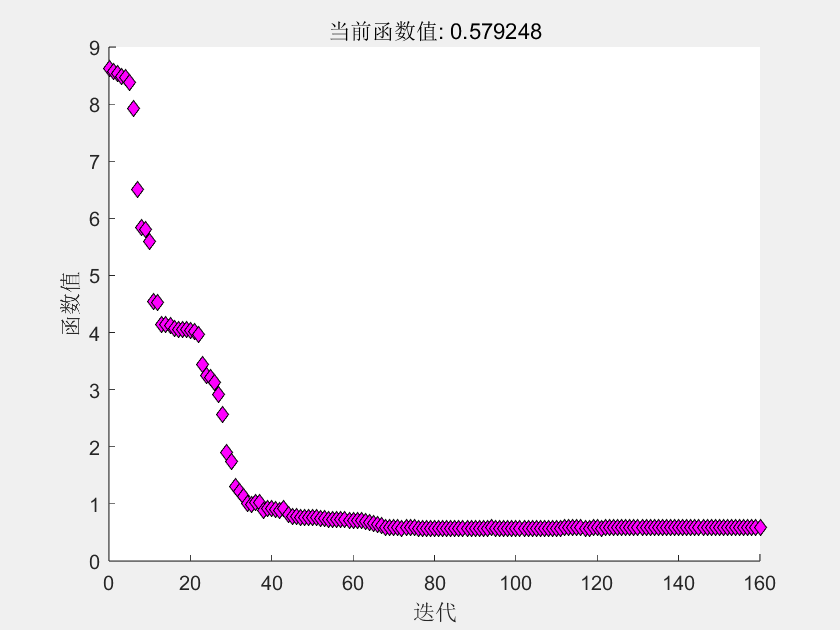


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>


% 将固定参数传递给 objfun
objfun = @(OptimInput)GetGoalError(OptimInput,ADS,DatasetFile);

% 设置非默认求解器选项
options = optimoptions("fmincon","Display","iter","PlotFcn","optimplotfval");

% 求解
[solution,objectiveValue] = fmincon(objfun,x0,[],[],[],[],lb,ub,[],options);


% 清除变量
clearvars objfun options


### S参数优化结果

% 设置变量为优化后的变量
ZPort1 = solution(1);
ZPort2 = solution(2);
ZPort4 = solution(3);
ZPort5 = solution(4);
Zc1 = solution(5);
Zc2 = solution(6);

RunSimWithParameter(ADS, 'ZPort1', ZPort1, 'ZPort2', ZPort2, 'ZPort4', ZPort4, 'ZPort5', ZPort5, 'Zc1', Zc1, 'Zc2', Zc2);

% 读取结果
ADS.ReadDataset(DatasetFile); 

% 提取S参数
[S41, Freq] = ADS.GetVariableAsFunction('S[4,1]', 'freq');
[S52, ~] = ADS.GetVariableAsFunction('S[5,2]', 'freq');
[S44, ~] = ADS.GetVariableAsFunction('S[4,4]', 'freq');
[S55, ~] = ADS.GetVariableAsFunction('S[5,5]', 'freq');

% 频率
fm = 200;
ftr = 10;
dBS41fm = 20*log10(abs(S41(fm+1)));
dBS52ftr = 20*log10(abs(S52(ftr+1)));
dBS44fm = 20*log10(abs(S44(fm+1)));
dBS55ftr = 20*log10(abs(S55(ftr+1)));

% 速度匹配结果
delta41 = -phase(S41)./Freq/2/pi;
delta52 = -phase(S52)./Freq/2/pi;

% 保存结果
filename = strcat(datestr(now),'优化结果及仿真结果.mat');
filename = erase(filename, ':');
save(filename,"solution","S41","S52","S44","S55")

SParameters = {'|S41|';'|S52|';'|S44|';'|S55|'};
Deltat = {'Deltatm200';'Deltatr10';'Deltatr190';'Deltatr210';'Deltatr390';'Deltatr410';'Deltatr590';'Deltatr610'};
SParameterValue = [dBS41fm; dBS52ftr; dBS44fm; dBS55ftr];
DeltatValue = [delta41(fm+1); delta52(ftr+1);delta52(fm-ftr+1);delta52(fm+ftr+1);delta52(2*fm-ftr+1);delta52(2*fm+ftr+1);delta52(3*fm-ftr+1);delta52(3*fm+ftr+1)];

阻抗匹配结果

table(SParameters, SParameterValue)

ans = 4×2 table
    SParameters    SParameterValue
    ___________    _______________

     {'|S41|'}          -3.5542   
     {'|S52|'}        -0.037847   
     {'|S44|'}          -27.384   
     {'|S55|'}           -28.95   


速度匹配结果

table(Deltat, DeltatValue)

ans = 8×2 table
        Deltat        DeltatValue
    ______________    ___________

    {'Deltatm200'}    7.1276e-09 
    {'Deltatr10' }    7.1276e-09 
    {'Deltatr190'}    7.0491e-09 
    {'Deltatr210'}    7.0503e-09 
    {'Deltatr390'}    5.7868e-09 
    {'Deltatr410'}    5.8467e-09 
    {'Deltatr590'}    6.2172e-09 
    {'Deltatr610'}    6.2443e-09 


% 时域仿真ADS接口
ADSTime = TADSInterface();
ADSTime.SetADSPaths(ADSInstallationDir);

[ADS][14:57:32] All required environmental variables and paths are set and checked.


% 设置时域仿真路径
ADSTime.NetlistFile = 'C:\Users\35406\Downloads\ADS-Matlab-Interface-master\ADS-Matlab-Interface-master\Demos\ADSProjects\Time_wrk\netlist.log';
TimeDatesetFile = 'C:\Users\35406\Downloads\ADS-Matlab-Interface-master\ADS-Matlab-Interface-master\Demos\ADSProjects\Time_wrk\Time.ds';

% 修改变量并启动仿真
RunSimWithParameter(ADSTime, 'ZPort1', ZPort1, 'ZPort2', ZPort2, 'ZPort4', ZPort4, ...
        'ZPort5', ZPort5, 'Zc1', Zc1, 'Zc2', Zc2, 'm', 0.6);

[ADS][14:57:33] The parameter with name "ZPort1" has been changed
[ADS][14:57:33]   at the netlist line 34:
[ADS][14:57:33]     ZPort1=36.6287628978
[ADS][14:57:33]     ↧↧↧ has changed to ↧↧↧
[ADS][14:57:33]     ZPort1=36.6287628978
[ADS][14:57:33] 
[ADS][14:57:33] The parameter with name "ZPort2" has been changed
[ADS][14:57:33]   at the netlist line 35:
[ADS][14:57:33]     ZPort2=20.1779112737
[ADS][14:57:33]     ↧↧↧ has changed to ↧↧↧
[ADS][14:57:33]     ZPort2=20.1779112737
[ADS][14:57:33] 
[ADS][14:57:33] The parameter with name "ZPort4" has been chang

### 时域仿真结果分析

% 读取结果文件
ADSTime.ReadDataset(TimeDatesetFile);

[ADS][14:58:14] Reading dataset file "C:\Users\35406\Downloads\ADS-Matlab-Interface-master\ADS-Matlab-Interface-master\Demos\ADSProjects\Time_wrk\Time.ds"
[ADS][14:58:15] 1) Reading vectorset "Tran1.TRAN"
[ADS][14:58:15]   Independent variables:
[ADS][14:58:15]     time
[ADS][14:58:15]   Dependent variables:
[ADS][14:58:15]     tr23
[ADS][14:58:15]     m60
[ADS][14:58:15]     tr68
[ADS][14:58:15]     m42
[ADS][14:58:15]     tr70
[ADS][14:58:15]     m19
[ADS][14:58:15]     tr28
[ADS][14:58:15]     tr64
[ADS][14:58:15]     tr51
[ADS][14:58:15]     tr48
[ADS][14:58:15]     m10
[ADS][14:58:15]     m52
[ADS][14:58:15]     m8
[ADS][14:58:15]     m61
[ADS][14:58:15]     tr65
[AD

% 调制路波形
[m1, time] = ADSTime.GetVariableAsFunction('m1', 'time');

[ADS][15:07:19] Variable "m1(time)" is found in the vectorset 1 ("Tran1.TRAN")


% 单元数
N = 72;

% 调制路波形
mwave = zeros(length(time), N+1);
for i = 0:N
    [mwave(:,i+1), ~] = ADSTime.GetVariableAsFunction(strcat('m',num2str(i)), 'time');
end

[ADS][15:07:19] Variable "m0(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m1(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m2(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m3(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m4(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m5(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m6(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m7(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m8(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m9(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m10(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m11(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "m12(time)" is found in t

% 主路波形
trwave = zeros(length(time), N+1);
for i = 0:N
    [trwave(:,i+1), ~] = ADSTime.GetVariableAsFunction(strcat('tr',num2str(i)), 'time');
end

[ADS][15:07:19] Variable "tr0(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr1(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr2(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr3(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr4(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr5(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr6(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr7(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr8(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr9(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr10(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr11(time)" is found in the vectorset 1 ("Tran1.TRAN")
[ADS][15:07:19] Variable "tr12(time)" 

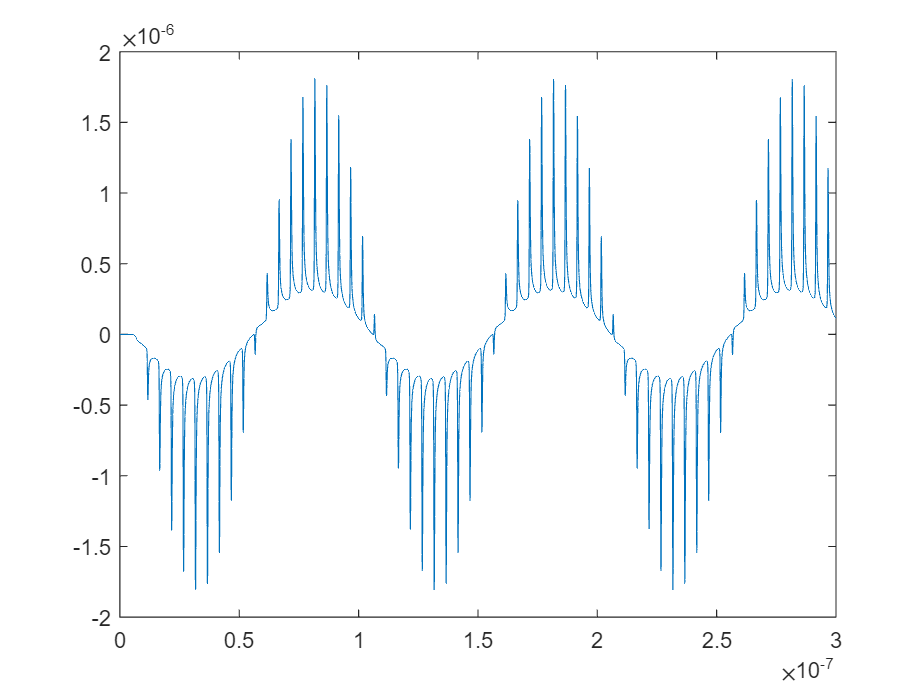

% 主路波形
figure;
plot(time, trwave(:,N+1))

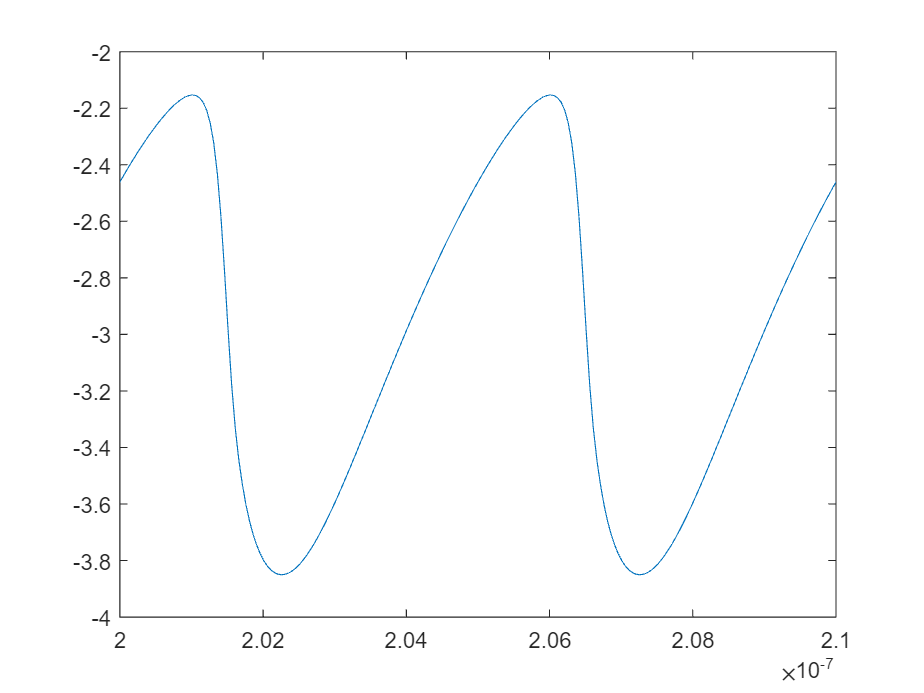

% 调制路波形
figure;
plot(time, mwave(:,N+1))
xlim([2, 2.1]*1e-7)

绘制放大曲线

delta41 = -phase(S41)./Freq/2/pi;
delta52 = -phase(S52)./Freq/2/pi;
NormT = delta52(ftr+1)/N*(0:N)*fm;

% 计算理论放大曲线
Cj0 = 8.47*1e-12;
M = 70;
Vj0 = 80;
V_static = 3;
a = 20*1e-3;
epsr = 1.3;
m = (max(mwave,[],'all') + V_static) / V_static;
fm = 200*1e6;
t = delta52(ftr+1)/N*(0:N);

[TheroyNormT, TheoryPA] = TheoryAmplified(Cj0, M, Vj0, V_static, a, epsr, Zc2, m, fm, t);

ans = 4×2 table
     Var1         Var2   
    _______    __________

    {'Mc1'}       0.19609
    {'Mc2'}         0.038
    {'Mc3'}     0.0050392
    {'Mc4'}    0.00051077


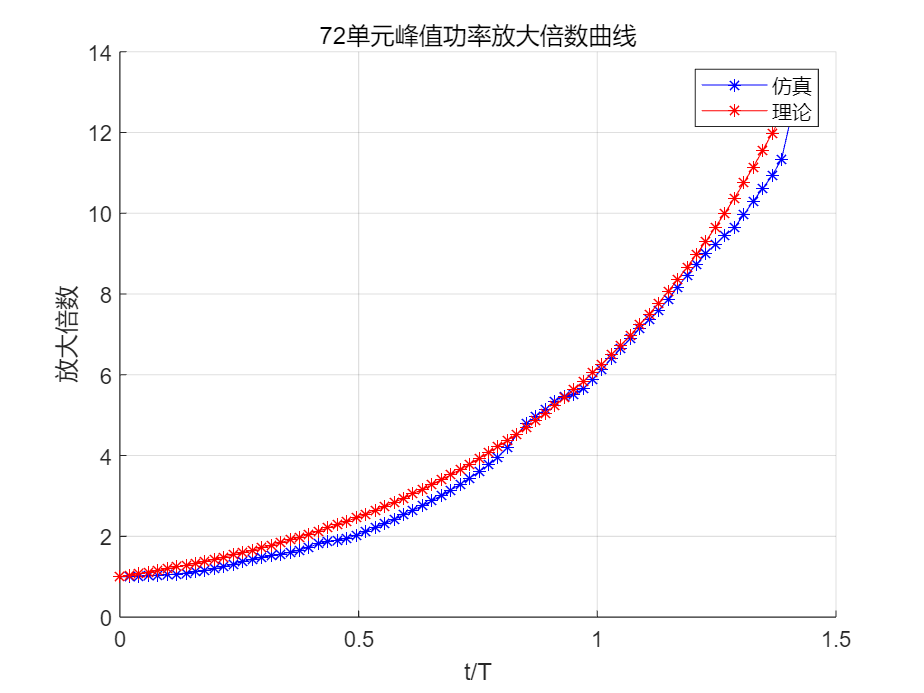


% 电压最大值
maxmwave = max(mwave);
maxtrwave = max(trwave);

% 归一化
Normlizedmaxtrwave = maxtrwave/maxtrwave(1);

% 归一化功率放大值
PAmpilfied = Normlizedmaxtrwave.^2;

figure;
hold on
plot(NormT, PAmpilfied, 'Color', 'b', 'Marker', '*')
plot(NormT, TheoryPA, 'Color', 'r', 'Marker', '*')
xlabel('t/T')
ylabel('放大倍数')
title(strcat(num2str(N), '单元峰值功率放大倍数曲线'))
legend('仿真', '理论')
grid on

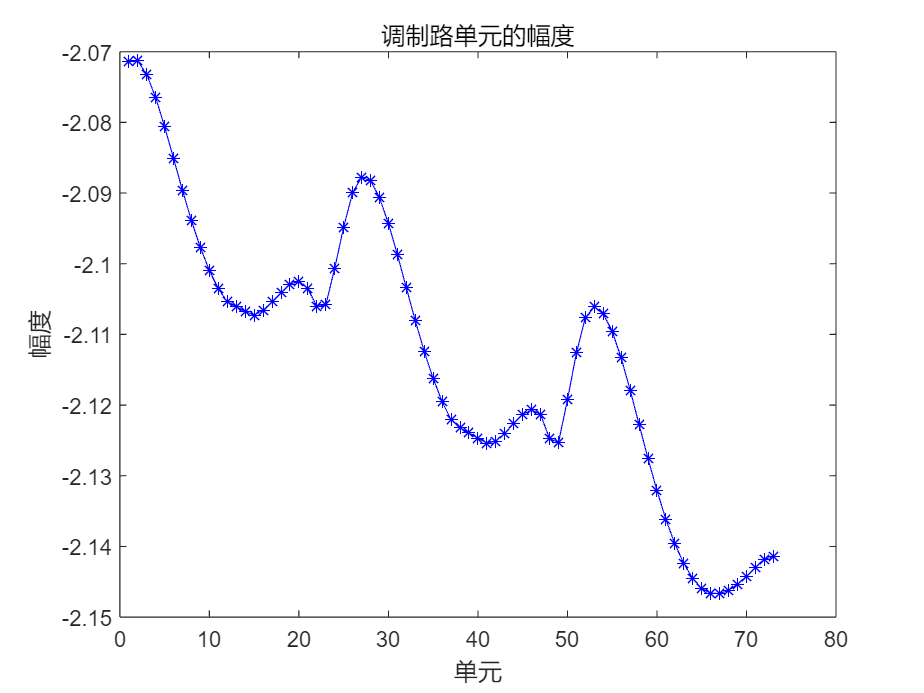

figure;
plot(maxmwave, 'Color', 'b', 'Marker', '*')
xlabel('单元')
ylabel('幅度')
title('调制路单元的幅度')